### Zadanie 2

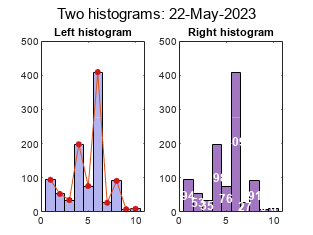

load data_cw3.mat
%min(x6)
%max(x6)
subplot(1, 2, 1);
h1=histogram(x6);
title('Left histogram');
h1.FaceColor = [0.5, 0.5, 0.9];
hold on
x1 = mean([h1.BinEdges(1:end-1); h1.BinEdges(2:end)]);
p2 = plot(x1, h1.Values);
p2.Marker = "o";
p2.MarkerFaceColor = [0.8, 0.1, 0.1];
p2.MarkerEdgeColor = [0.8, 0.1, 0.1];
p2.MarkerSize = 4;
hold off
subplot(1, 2, 2);
h2 = histogram(x6);
title('Right histogram');
h2.FaceColor = [0.4, 0.1, 0.6];
%text(x1(1), h2.Values(1)/2, string(h2.Values(1)), "FontSize", 9, ... 
  %  "FontWeight", 'bold', "HorizontalAlignment","center",'Color', [1, 1, 1])
%dla wszystkich analogicznie; na wektorach zamiast pojedynczych wartosci:
text(x1, h2.Values./2, string(h2.Values), "FontSize", 9, ... 
    "FontWeight", 'bold', "HorizontalAlignment","center",'Color', [1, 1, 1])
%str = sprintf('Two histograms ', )
sgtitle('Two histograms: ' + string(date));

### Zadanie 3

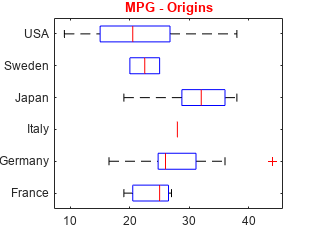

load carsmall.mat
figure
%dane tekstowe wygodniej zamienic na kategoryczne, bo umozliwiaja wiele operacji
Origin = categorical(string(Origin));
%categories(Origin)
boxplot(MPG, Origin, "Orientation","horizontal");
title('MPG - Origins', 'Color', [1,0,0]);

### Zadanie 4

Tabele danych

%preparacja danych
n = 1000;
d1 = normrnd(2, 3, n, 1);
%losowanie indeksow do wstawienia Inf jako niepoprawnych danych
    %datasample zamiast valrand, zeby miec mozliwosc unikniecia duplikatow
idx1 = datasample(1:n, 20, 'Replace',false);
d1(idx1) = Inf;
%sum(d1==Inf)
kolv=categorical({'red';'pink';'blue';'violet';'NA';'green';'orange';'cyan';'brown';'black'});
d2 = datasample(kolv, n);
d3 = datetime(2019,1,1) + days(0:5:5*n-1)';
%d3 obrocilismy zeby mialo poprawne wymiary 1000x1, a nie 1x1000
idx3 = datasample(1:n, 15, 'Replace',false);
d3(idx3) = '';
strv=["a";"b";"c";"d";"e";"f";""];
d4 = datasample(strv, n);
%tworzenie tabeli z wektorow
data1 = table(d1, d2, d3, d4);
%tabela komorkowa - {}
data1.Properties.VariableNames = ...
    {'Value','Color','Date', 'Letter'};
data1 = movevars(data1, "Date", "Before", "Value");
head(data1)

       Date         Value      Color     Letter
    ___________    ________    ______    ______

    01-Jan-2019     -1.1791    cyan       ""   
    06-Jan-2019      2.9381    violet     "e"  
    11-Jan-2019    -0.26852    NA         "d"  
    16-Jan-2019     0.66713    green      "e"  
    21-Jan-2019      6.5504    orange     "a"  
    26-Jan-2019     -4.6323    cyan       "a"  
    31-Jan-2019       5.707    NA         "c"  
    05-Feb-2019      1.5527    orange     "e"  



summary(data1)

Variables:

    Date: 1000×1 datetime

        Values:

            Min             01-Jan-2019  
            Median          31-Oct-2025  
            Max             04-Sep-2032  
            NumMissing      15           

    Value: 1000×1 double

        Values:

            Min       -7.3461 
            Median     2.2457 
            Max           Inf 

    Color: 1000×1 categorical

        Values:

            NA          122   
            black        75   
            blue        101   
            brown        91   
            cyan        102   
            green        96   
            orange      107   
            pink        103   
            red          95   
            violet      108   

    Letter: 1000×1 string



sum(ismissing(data1))

ans =     15     0     0     0


mv = {Inf, 'NA', "", ''}; %wektor wartosci, ktore powinny byc traktowane jako brakujace
data1 = standardizeMissing(data1, mv);
sum(ismissing(data1))

ans =     15    20   122   147


%summary(data1)
%nieduzo brakow/outlierow - mozna usunac rekordy; duzo - lepiej uzupelnic
data1.Date = fillmissing(data1.Date, "linear"); %zmienna liczbowa
data1.Color = fillmissing(data1.Color, "nearest"); %zmienna kategoryczna
data1.Letter = fillmissing(data1.Letter, "nearest");
data1.Value = fillmissing(data1.Value, "movmean", 3);
sum(ismissing(data1))

ans =      0     0     0     0


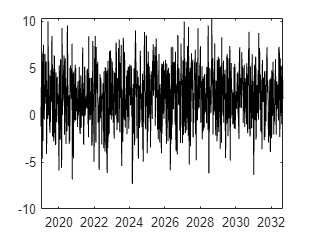

writetable(data1, "data1.csv");
%zad 8 wykres na podstawie wektora
p8 = plot(data1.Date, data1.Value);
p8.Color = [0,0,0];

### Zadanie 9

Plik csv

fname = 'pacjenci.csv';
%funkcja badajaca najlepsze opcje importu pliku
opts = detectImportOptions(fname);
dpacjenci = readtable(fname, opts);
dpacjenci.Properties.VariableNames = {'Plec', 'Waga', 'Wzrost', 'Wiek', 'Palacy'};
%summary(dpacjenci)
sum(isoutlier(dpacjenci, 1, "DataVariables", vartype("numeric")))

ans =      0     2     7     2    56


dpacjenci.Waga = filloutliers(dpacjenci.Waga, "linear");
dpacjenci.Wzrost = filloutliers(dpacjenci.Wzrost, "linear");
dpacjenci.Wiek = filloutliers(dpacjenci.Wiek, "linear");
sum(isoutlier(dpacjenci, 1, "DataVariables", vartype("numeric")))

ans =      0     0     0     0    56


%sum(isoutlier(dpacjenci(:,vartype("numeric"))))
%Inf i '' jako wartosci brakujace:
mv9 = {Inf, "", ''};
dpacjenci = standardizeMissing(dpacjenci, mv);
sum(ismissing(dpacjenci))

ans =      7     3     0     3     5


dpacjenci.Plec = fillmissing(dpacjenci.Plec, "nearest");
dpacjenci.Waga = fillmissing(dpacjenci.Waga, "linear");
dpacjenci.Wzrost = fillmissing(dpacjenci.Wzrost, "linear");
dpacjenci.Wiek = fillmissing(dpacjenci.Wiek, "linear");
dpacjenci.Palacy = fillmissing(dpacjenci.Palacy, "movmean", 3);
sum(ismissing(dpacjenci))

ans =      0     0     0     0     0


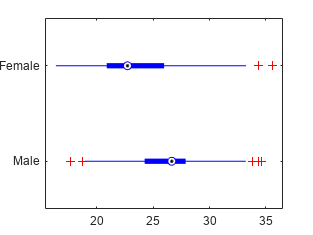

dpacjenci.WzrostM = dpacjenci.Wzrost*2.54/100;
dpacjenci.WagaKg = dpacjenci.Waga*0.453;
dpacjenci.BMI = dpacjenci.WagaKg ./ (dpacjenci.WzrostM .^ 2);
boxplot(dpacjenci.BMI, dpacjenci.Plec, "Orientation","horizontal","BoxStyle","filled", "MedianStyle","target");